# Basic Hierarchy

Instructions are in the task pane to the left. Complete and submit each task one at a time. This code sets up the activity.

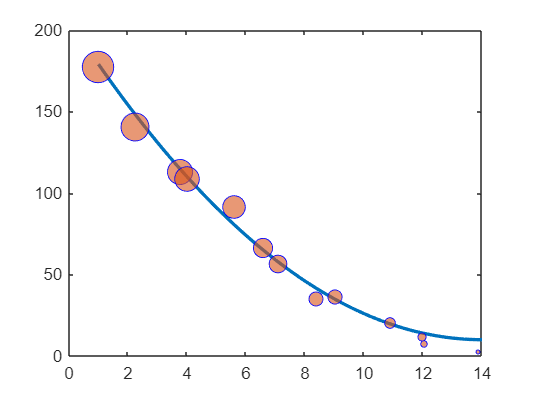

x = (1:13) + rand(1,13);
y = 10+(x-14).^2 - 5*randn(1,13);
xModel = 1:0.2:14;
yModel = 10 + (xModel-14).^2;
fig = figure;
plot(xModel,yModel,"LineWidth",2);
hold on
scatter(x,y,2*y,"filled","MarkerFaceAlpha",0.6,"MarkerEdgeColor","b");

## Task 1

The goal of this exercise is to find the scatter and line plot objects by using the graphics hierarchy.

Recall that one way to get the current axes object is to use the function `gca`. Another way of getting the axes graphics object is to use the graphics hierarchy.

Since axes is a *child* of the figure, you can use the `Children` property of the figure object `fig` to get the axes object.

**TASK1**

Get the axes graphics object using the `Children` property and store it in `ax`.

**Hint1**

Assign `fig.Children` to a variable.

ax=fig.Children

ax =   Axes with properties:

             XLim: [0 14]
             YLim: [0 180]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


## Task 2

The scatter and line plots are the children of the axes.

**TASK2**

Get the `Children` of the axes object and store the result in `p`.

**Hint2**

Assign `ax.Children` to a variable.

p=ax.Children

p =   2×1 graphics array:

  Scatter
  Line


## Task 3

You can examine the variable `p` by double clicking the variable name in the workspace.

**TASK3**

Notice that the variable `p` is an array containing two graphics objects. That is because the axes has two children, the scatter plot and the line plot. Extract the first element of this array and assign it to `sp`.

**Hint3**

Index into `p` using `p``(``1``)`.

sp = p(1)

sp =   Scatter with properties:

              XData: [1.0057 2.2524 3.7957 4.0153 5.5988 6.6038 7.1051 8.3819 9.0365 10.8904 11.9809 12.0599 13.8905]
              YData: [177.6294 141.0775 112.8871 109.0287 91.8585 66.6981 56.5401 35.4480 36.3512 20.3884 12.0165 7.6192 2.9074]
              ZData: [1×0 double]
           SizeData: [355.2588 282.1550 225.7741 218.0574 183.7171 133.3961 113.0803 70.8959 72.7024 40.7767 24.0330 15.2384 5.8147]
              CData: [0.8500 0.3250 0.0980]
             Marker: 'o'
    MarkerEdgeColor: [0 0 1]
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000

  Show all properties


## Task 4

Every graphics object has a (read-only) `Type` property.

**TASK4**

Find the type of the object `sp` and store it in `spType`.

**Hint4**

You can use dot notation to find the `Type` property of `sp`.

`outputVariableName` `=` `graphicsObject.Type``;`

spType=sp.Type

spType = 'scatter'